% 概率论实验问题1，比较二项分布，泊松分布以及CLT
do_plot = 1     % 是否进行单次图像绘制？0 false | 1 true

do_plot = 1

n_step  = 1

n_step = 1

n       = 10 * n_step

n = 10

p_step  = 0.1

p_step = 0.1000

p       = 1* p_step

p = 0.1000

x_max   = 14

x_max = 14

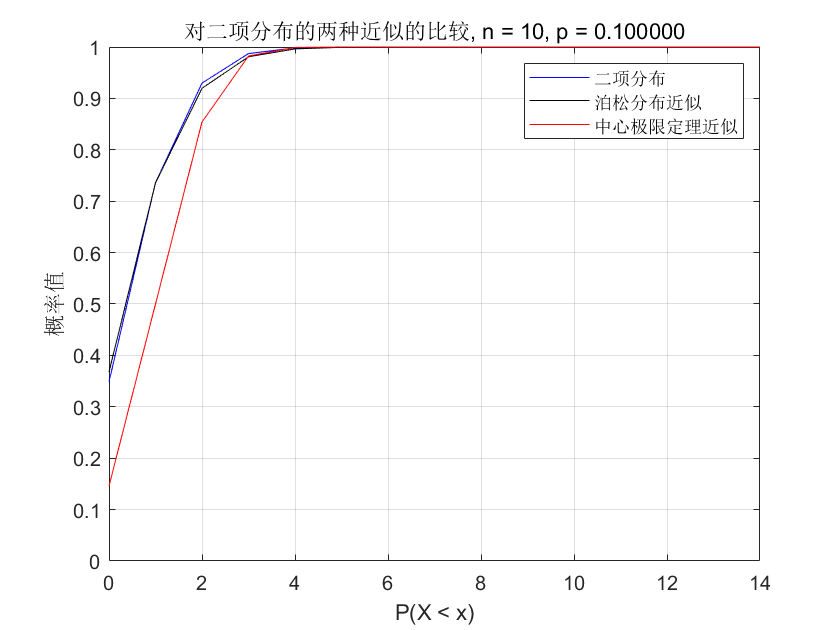

fig_num = 1;
if(do_plot)
    figure(1);
    fig_num = fig_num + 1;
end
proxError(n, p, x_max, do_plot);    % 绘制固定n,p的图像

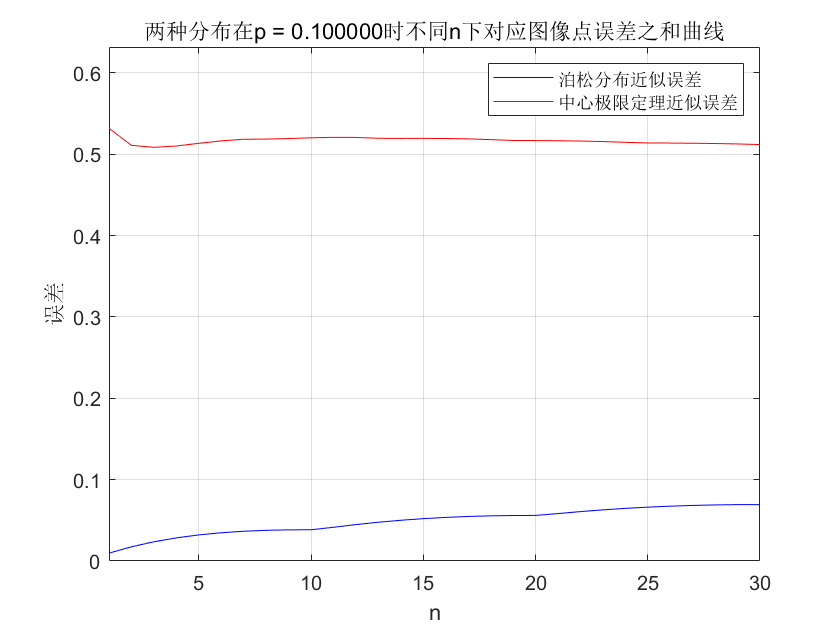

% 固定 p = 0.02 | n in range(5, 20) 的 误差图表
errors_p = zeros(1, 30);
errors_clt = zeros(1, 30);
for n = 1:30
    [e_p, e_clt] = proxError(n, p, x_max, 0);
    errors_p(n) = e_p;
    errors_clt(n) = e_clt;
end
figure(fig_num);
ns = 1:1:30;
plot(ns, errors_p, "b");
hold on; axis on; grid on;
plot(ns, errors_clt, "r");
gb = max( max(errors_p), max(errors_clt) ) + 0.1; 
xlim([1, 30]);
ylim([0, gb]);
legend(["泊松分布近似误差", "中心极限定理近似误差"]);
xlabel("n"); ylabel("误差");
str = sprintf("两种分布在p = %f时不同n下对应图像点误差之和曲线", p);
title(str);

fig_num = fig_num + 1;

%固定n = 20 时, p = 0.01:0.03:0.43
n = 20

n = 20

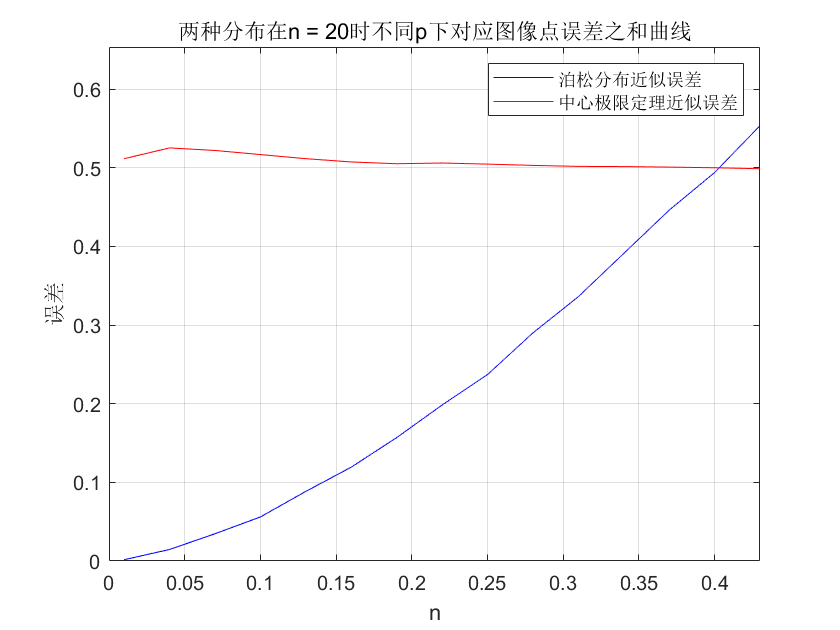

errors_p = zeros(1, 15);
errors_clt = zeros(1, 15);
cnt = 1;
for p = 0.01:0.03:0.43
    [e_p, e_clt] = proxError(n, p, x_max, 0);
    errors_p(cnt) = e_p;
    errors_clt(cnt) = e_clt;
    cnt = cnt + 1;
end
figure(fig_num);
ps = 0.01:0.03:0.43;
plot(ps, errors_p, "b");
hold on; axis on; grid on;
plot(ps, errors_clt, "r");
gb = max( max(errors_p), max(errors_clt) ) + 0.1; 
xlim([0, 0.43]);
ylim([0, gb]);
legend(["泊松分布近似误差", "中心极限定理近似误差"]);
xlabel("n"); ylabel("误差");
str = sprintf("两种分布在n = %d时不同p下对应图像点误差之和曲线", n);
title(str);

function [e_sum_p, e_sum_clt] = proxError(n, p, x_max, do_plot)
clf;
bin_y   = zeros(1, x_max);
p_y     = zeros(1, x_max);
clt_y   = zeros(1, x_max);
xs = 0:1:x_max;
for x = 0:x_max
    bin_y(x+1) = binocdf(x, n, p);
    p_y(x+1) = poisscdf(x, n*p);
    clt_y(x+1) = CLT(n, p, x);
end
if(do_plot)
    % 单次固定n， p曲线的绘制
    plot(xs, bin_y, "b");
    hold on; axis on; grid on;
    plot(xs, p_y, "k");
    plot(xs, clt_y, "r");
    xlim([0, x_max]);
    ylim([0, 1]);
    legend(["二项分布", "泊松分布近似", "中心极限定理近似"]);
    xlabel("P(X < x)"); ylabel("概率值");
    str = sprintf("对二项分布的两种近似的比较, n = %d, p = %f", n, p);
    title(str);
end
error_p = p_y - bin_y;          % 泊松近似误差向量
error_clt = clt_y - bin_y;      % clt近似误差向量
e_sum_p = norm(error_p, 1);   % 泊松近似误差，取1-范数
e_sum_clt = norm(error_clt, 1); % clt近似误差
end   % end of the function

function out = CLT(n, p, x)
% De Moivre-Laplace 中心极限定理 极限分布
% n 贝努里试验总次数
% p 试验成功概率
% x 试验成功次数小于等于x (由中心极限定理近似于phi(inter),inter的计算见下)
inter = (x - n * p) / sqrt(n * p * (1 - p));
out = normcdf(inter);
end